## Initialize

clear all;

addpath(genpath('matlabfunctions'))
addpath(genpath('/Applications/MATLAB_TOOLBOXES'))

area_metric = 3; % 1=WM, 2=pial, 3=avg


## Load & Format Macaque Data

load('./completeData/monkey_data')

% designate colors for general species comparisons
human_blue = [0 0.4470 0.7410];
monkey_orange = [0.8500 0.3250 0.0980];

% designate individual maps belonging to regions and their color
EVCrois_monkey=1:3; EVCcolor=[0.1 0.6 1];
V4rois_monkey=4:5; V4color=[1 0.2 1];
ventralrois_monkey=6:10; ventralcolor=[1 0.2 0.2];
dorsalrois_monkey=11:12; dorsalcolor=[1 .8 0];
lateralrois_monkey=13:16; lateralcolor=[0 1 0];
parietalrois_monkey=17:21; parietalcolor=[0 1 1];

% concatenate all human area ROIs, labels, and colors
region_rois_monkey = {EVCrois_monkey;V4rois_monkey;ventralrois_monkey;dorsalrois_monkey;parietalrois_monkey;lateralrois_monkey};
colorscale_monkey_all=[repmat(EVCcolor,length(EVCrois_monkey),1);...
    repmat(V4color,length(V4rois_monkey),1);...
    repmat(ventralcolor,length(ventralrois_monkey),1);...
    repmat(dorsalcolor,length(dorsalrois_monkey),1);...
    repmat(lateralcolor,length(lateralrois_monkey),1);...
    repmat(parietalcolor,length(parietalrois_monkey),1)];

% specify color maps for different visualiztion needs
colorscale_monkey_all_inv = flipud(colorscale_monkey_all);
colorscale_region_monkey=[EVCcolor;EVCcolor;EVCcolor;V4color;ventralcolor;dorsalcolor;lateralcolor;parietalcolor];
colorscale_unique_monkey = unique(colorscale_region_monkey,'stable','rows');
colorscale_region_monkey_inv = flipud(colorscale_region_monkey);

% rename areas to pull out of struct
for i = 1:2
    surfacearea_smoothwm{i} = monkey_data.surfacearea_smoothwm{i};
    surfacearea_pial{i} = monkey_data.surfacearea_pial{i};
end

% full brain surface area
total_area_cat_monkey = [monkey_data.total_size(:,1)' monkey_data.total_size(:,2)'];
total_area_sum_monkey = monkey_data.total_size(:,1)' + monkey_data.total_size(:,2)';

% get average of white matter and pial surface area
surfacearea_avg = cellfun(@(x,y) (x+y)/2, surfacearea_smoothwm, surfacearea_pial,'UniformOutput',false);

% get sum, concatenated, and average hemispheres depending on area metric
if area_metric == 1
    % use this for WM 
    surfacearea_bothhemis_monkey = surfacearea_smoothwm{1} + surfacearea_smoothwm{2};
    surfacearea_catbothhemis_monkey=cat(2,surfacearea_smoothwm{1},surfacearea_smoothwm{2});
    surfacearea_monkey = surfacearea_smoothwm;
elseif area_metric ==2
    % use this for pial 
    surfacearea_bothhemis_monkey = surfacearea_pial{1} + surfacearea_pial{2};
    surfacearea_catbothhemis_monkey=cat(2,surfacearea_pial{1},surfacearea_pial{2});
    surfacearea_monkey = surfacearea_pial;
elseif area_metric == 3
    % use this for average of WM and pial surface
    surfacearea_catbothhemis_monkey = cat(2,surfacearea_avg{1},surfacearea_avg{2});
    surfacearea_bothhemis_monkey = surfacearea_avg{1} + surfacearea_avg{2};
    surfacearea_monkey = surfacearea_avg;
end

% sum over dorsal and ventral components of EVC for concatenated hemis
V1_bothhemis_combined = surfacearea_catbothhemis_monkey(1,:) + surfacearea_catbothhemis_monkey(2,:);
V2_bothhemis_combined = sum(surfacearea_catbothhemis_monkey(3:4,:),1);
V3_bothhemis_combined = sum(surfacearea_catbothhemis_monkey(5:6,:),1);
V4_bothhemis_combined = sum(surfacearea_catbothhemis_monkey(7:8,:),1);
V4A_bothhemis_combined = sum(surfacearea_catbothhemis_monkey(9:10,:),1);

cat_monkey = [V1_bothhemis_combined;V2_bothhemis_combined;...
    V3_bothhemis_combined;V4_bothhemis_combined;V4A_bothhemis_combined;surfacearea_catbothhemis_monkey(11:end,:)];

% sum over dorsal and ventral components of EVC for summed hemis
V1_bothhemis_combined = surfacearea_bothhemis_monkey(1,:) + surfacearea_bothhemis_monkey(2,:);
V2_bothhemis_combined = sum(surfacearea_bothhemis_monkey(3:4,:),1);
V3_bothhemis_combined = sum(surfacearea_bothhemis_monkey(5:6,:),1);
V4_bothhemis_combined = sum(surfacearea_bothhemis_monkey(7:8,:),1);
V4A_bothhemis_combined = sum(surfacearea_bothhemis_monkey(9:10,:),1);

sum_monkey = [V1_bothhemis_combined;V2_bothhemis_combined;...
    V3_bothhemis_combined;V4_bothhemis_combined;V4A_bothhemis_combined;surfacearea_bothhemis_monkey(11:end,:)];

% average over broad areas for raw surface area measurements
V4_combined_monkey = mean(sum_monkey(4:5,:),1);
ventral_combined_monkey = mean(sum_monkey(ventralrois_monkey-5,:),1);
dorsal_combined_monkey = mean(sum_monkey(dorsalrois_monkey-5,:),1);
lateral_combined_monkey = mean(sum_monkey(lateralrois_monkey-5,:),1);
parietal_combined_monkey = mean(sum_monkey(parietalrois_monkey-5,:),1);

region_monkey = [sum_monkey(1:3,:);V4_combined_monkey;ventral_combined_monkey;...
    dorsal_combined_monkey;lateral_combined_monkey;parietal_combined_monkey];

% summed hemis normalized by V1
normv1_monkey = sum_monkey./V1_bothhemis_combined;

% average over broad regions for surface area measurements relative to V1
normV4_combined_monkey = mean(normv1_monkey(4:5,:),1);
normventral_combined_monkey = mean(normv1_monkey(ventralrois_monkey-5,:),1);
normdorsal_combined_monkey = mean(normv1_monkey(dorsalrois_monkey-5,:),1);
normlateral_combined_monkey = mean(normv1_monkey(lateralrois_monkey-5,:),1);
normparietal_combined_monkey = mean(normv1_monkey(parietalrois_monkey-5,:),1);

region_monkey_normv1 = [normv1_monkey(1:3,:);normV4_combined_monkey;normventral_combined_monkey;...
    normdorsal_combined_monkey;normlateral_combined_monkey;normparietal_combined_monkey];

% monkey area labels
alllabels_monkey = cat(2,{'V1','V2','V3','V4','V4A'},monkey_data.labels(11:end));
alllabels_monkey_region = {'V1','V2','V3','V4','Ventral','Dorsal','Lateral','Parietal'};

## Load & Format Adult Human Data

load('./completeData/human_data')

% designate individual maps belonging to regions and their color
EVCrois_human=1:3; EVCcolor=[0 0 0.7];
V4rois_human=4; V4color=[0.6 0 0.6];
ventralrois_human=5:8; ventralcolor=[0.6 0.1 0.1];
dorsalrois_human=9:10; dorsalcolor=[0.8 .5 0];
lateralrois_human=11:14; lateralcolor=[0.2784    0.5216    0.1451];
parietalrois_human=15:21; parietalcolor=[0 0.7 0.7];

% concatenate all human area ROIs, labels, and colors
region_rois_human = {EVCrois_human;V4rois_human;ventralrois_human;dorsalrois_human;lateralrois_human;parietalrois_human};
colorscale_human_all=[repmat(EVCcolor,length(EVCrois_human),1);...
    repmat(V4color,length(V4rois_human),1);...
    repmat(ventralcolor,length(ventralrois_human),1);...
    repmat(dorsalcolor,2,1);...
    repmat(lateralcolor,length(lateralrois_human),1);...
    repmat(parietalcolor,length(parietalrois_human),1)];

% specify color maps for different visualiztion needs
colorscale_human_all_inv = flipud(colorscale_human_all);
colorscale_region_human=[EVCcolor;EVCcolor;EVCcolor;V4color;ventralcolor;dorsalcolor;lateralcolor;parietalcolor];
colorscale_unique_human = unique(colorscale_region_human,'stable','rows');
colorscale_region_human_inv = flipud(colorscale_region_human);

% full brain surface area
total_area_cat_human = [human_data.total_size(:,1)' human_data.total_size(:,2)'];
total_area_sum_human = human_data.total_size(:,1)' + human_data.total_size(:,2)';

% rename areas to pull out of struct
for i = 1:2
    surfacearea_smoothwm{i} = human_data.surfacearea_smoothwm{i};
    surfacearea_pial{i} = human_data.surfacearea_pial{i};
end

% get average of white matter and pial surface area
surfacearea_avg = cellfun(@(x,y) (x+y)/2, human_data.surfacearea_smoothwm, human_data.surfacearea_pial,'UniformOutput',false);

% get sum, concatenated, and average hemispheres depending on area metric
if area_metric == 1
    % use this for WM 
    surfacearea_bothhemis_human = surfacearea_smoothwm{1} + surfacearea_smoothwm{2};
    surfacearea_catbothhemis_human=cat(2,surfacearea_smoothwm{1},surfacearea_smoothwm{2});
    surfacearea_human = surfacearea_smoothwm;
elseif area_metric ==2
    % use this for pial 
    surfacearea_bothhemis_human = surfacearea_pial{1} + surfacearea_pial{2};
    surfacearea_catbothhemis_human=cat(2,surfacearea_pial{1},surfacearea_pial{2});
    surfacearea_human = surfacearea_pial;
elseif area_metric == 3
    % use this for average of WM and pial surface
    surfacearea_catbothhemis_human = cat(2,surfacearea_avg{1},surfacearea_avg{2});
    surfacearea_bothhemis_human = surfacearea_avg{1} + surfacearea_avg{2};
    surfacearea_human = surfacearea_avg;
end

% sum over dorsal and ventral components of EVC for concatenated hemis
V1_bothhemis_combined = surfacearea_catbothhemis_human(1,:) + surfacearea_catbothhemis_human(2,:);
V2_bothhemis_combined = sum(surfacearea_catbothhemis_human(3:4,:),1);
V3_bothhemis_combined = sum(surfacearea_catbothhemis_human(5:6,:),1);
V4_bothhemis_combined = surfacearea_catbothhemis_human(7,:);

cat_human = [V1_bothhemis_combined;V2_bothhemis_combined;...
    V3_bothhemis_combined;V4_bothhemis_combined;surfacearea_catbothhemis_human(8:end,:)];

% sum over dorsal and ventral components of EVC for summed hemis
V1_bothhemis_combined = surfacearea_bothhemis_human(1,:) + surfacearea_bothhemis_human(2,:);
V2_bothhemis_combined = sum(surfacearea_bothhemis_human(3:4,:),1);
V3_bothhemis_combined = sum(surfacearea_bothhemis_human(5:6,:),1);
V4_bothhemis_combined = surfacearea_bothhemis_human(7,:);

sum_human = [V1_bothhemis_combined;V2_bothhemis_combined;...
    V3_bothhemis_combined;V4_bothhemis_combined;surfacearea_bothhemis_human(8:end,:)];

% average over broad areas for raw surface area measurements
ventral_combined_human = mean(sum_human(ventralrois_human,:),1);
dorsal_combined_human = mean(sum_human(dorsalrois_human,:),1);
lateral_combined_human = mean(sum_human(lateralrois_human,:),1);
parietal_combined_human = mean(sum_human(parietalrois_human,:),1);

region_human = [sum_human(1:4,:);ventral_combined_human;dorsal_combined_human;...
    lateral_combined_human;parietal_combined_human];

% summed hemis normalized by V1
normv1_human = sum_human./V1_bothhemis_combined;

% average over broad regions for surface area measurements relative to V1
normventral_combined_human = mean(normv1_human(ventralrois_human,:),1);
normdorsal_combined_human = mean(normv1_human(dorsalrois_human,:),1);
normlateral_combined_human = mean(normv1_human(lateralrois_human,:),1);
normparietal_combined_human = mean(normv1_human(parietalrois_human,:),1);

region_human_normv1 = [normv1_human(1:4,:);normventral_combined_human;normdorsal_combined_human;...
    normlateral_combined_human;normparietal_combined_human];

% human area labels
alllabels_human = cat(2,{'V1','V2','V3'},human_data.labels(7:end));
alllabels_humans_region = {'V1','V2','V3','V4','Ventral','Dorsal','Lateral','Parietal'};
alllabels_combined = {'EVC','V4','Ventral','Dorsal','Lateral','Parietal'};

## Load & Format Neonate Human Data

load('./completeData/neo_data.mat');

% rename areas to pull out of struct
for i = 1:2
    surfacearea_smoothwm{i} = neo_data.surfacearea_smoothwm{i};
    surfacearea_pial{i} = neo_data.surfacearea_pial{i};
end

% get average of white matter and pial surface area
surfacearea_avg = cellfun(@(x,y) (x+y)/2, neo_data.surfacearea_smoothwm, neo_data.surfacearea_pial,'UniformOutput',false);

% get sum, concatenated, and average hemispheres depending on area metric
if area_metric == 1
    % use this for WM 
    surfacearea_bothhemis_neo = surfacearea_smoothwm{1} + surfacearea_smoothwm{2};
    surfacearea_catbothhemis_neo=cat(2,surfacearea_smoothwm{1},surfacearea_smoothwm{2});
    surfacearea_neo = surfacearea_smoothwm;
elseif area_metric ==2
    % use this for pial 
    surfacearea_bothhemis_neo = surfacearea_pial{1} + surfacearea_pial{2};
    surfacearea_catbothhemis_neo=cat(2,surfacearea_pial{1},surfacearea_pial{2});
    surfacearea_neo = surfacearea_pial;
elseif area_metric == 3
    % use this for average of WM and pial surface
    surfacearea_catbothhemis_neo = cat(2,surfacearea_avg{1},surfacearea_avg{2});
    surfacearea_bothhemis_neo = surfacearea_avg{1} + surfacearea_avg{2};
    surfacearea_neo = surfacearea_avg;
end

% restructure data for concatenated hemis
V1_bothhemis_combined = surfacearea_catbothhemis_neo(1,:) + surfacearea_catbothhemis_neo(2,:);
V2_bothhemis_combined = sum(surfacearea_catbothhemis_neo(3:4,:),1);
V3_bothhemis_combined = sum(surfacearea_catbothhemis_neo(5:6,:),1);
V4_bothhemis_combined = surfacearea_catbothhemis_neo(7,:);

cat_neo = [V1_bothhemis_combined;V2_bothhemis_combined;...
    V3_bothhemis_combined;V4_bothhemis_combined;surfacearea_catbothhemis_neo(8:end,:)];

% restructure data to get area categories we want to display
V1_bothhemis_combined = surfacearea_bothhemis_neo(1,:) + surfacearea_bothhemis_neo(2,:);
V2_bothhemis_combined = sum(surfacearea_bothhemis_neo(3:4,:),1);
V3_bothhemis_combined = sum(surfacearea_bothhemis_neo(5:6,:),1);
V4_bothhemis_combined = surfacearea_bothhemis_neo(7,:);

sum_neo = [V1_bothhemis_combined;V2_bothhemis_combined;...
    V3_bothhemis_combined;V4_bothhemis_combined;surfacearea_bothhemis_neo(8:end,:)];

% average over broad areas for raw surface area measurements
ventral_combined_neo = mean(sum_neo(ventralrois_human,:),1);
dorsal_combined_neo = mean(sum_neo(dorsalrois_human,:),1);
lateral_combined_neo = mean(sum_neo(lateralrois_human,:),1);
parietal_combined_neo = mean(sum_neo(parietalrois_human,:),1);

region_neo = [sum_neo(1:4,:);ventral_combined_neo;dorsal_combined_neo;...
    lateral_combined_neo;parietal_combined_neo];


## Fig 2A: Surface area measurements of macaques

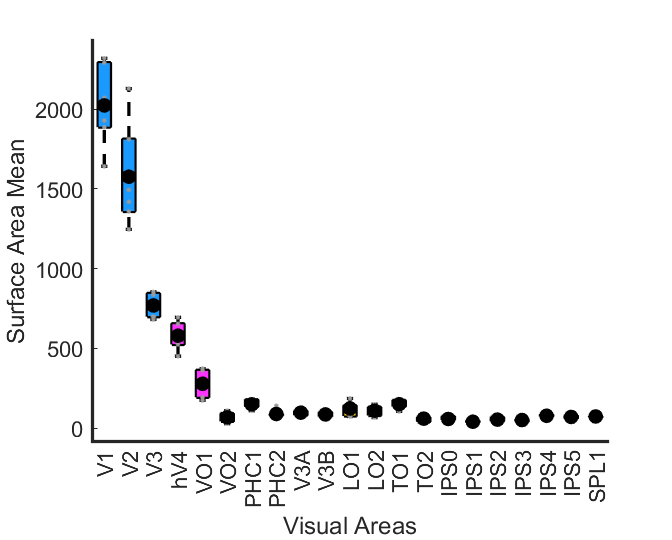

% create boxplot for each monkey visual map colored by the region
figure();
hold on
h=boxplot(sum_monkey','notch','off','colors',[0 0 0],'symbol','');
set(h,{'linew'},{2})
h = findobj(gca,'Tag','Box');
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),(colorscale_monkey_all_inv(j,:)),'FaceAlpha',1);
end
hold on
cscale = zeros(size(colorscale_monkey_all,1),3);
% plot gray dots for individual subjects and large black dot for average
plotSpread(sum_monkey','distributionColors',cscale+[.6 .6 .6],'spreadWidth',.5)
plot(nanmean(sum_monkey'),'k.','MarkerSize',30);

xlim([0.5 size(sum_monkey,1)+.5])
yticks(0:500:2000)
ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
ax.FontSize = 13;
set(gca,'xtick',[1:length(alllabels_human)],'xticklabel', alllabels_human);
xlabel('Visual Areas');
ylabel('Surface Area Mean');
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);

% display average range of each region based on max/min, reported in text
for i = 1:size(sum_monkey,1)
    area_range(i) = max(sum_monkey(i,:),[],'omitnan')/min(sum_monkey(i,:),[],'omitnan');
end

temp_rois = {1:4,ventralrois_monkey,dorsalrois_monkey,lateralrois_monkey,parietalrois_monkey};
for i = 1:length(temp_rois)
    disp(mean(area_range(temp_rois{i}),'all','omitnan'))
end

    1.4779

    2.1750

    2.3891

    1.9784

    1.8049



## Fig 2B: Surface area measurements of humans

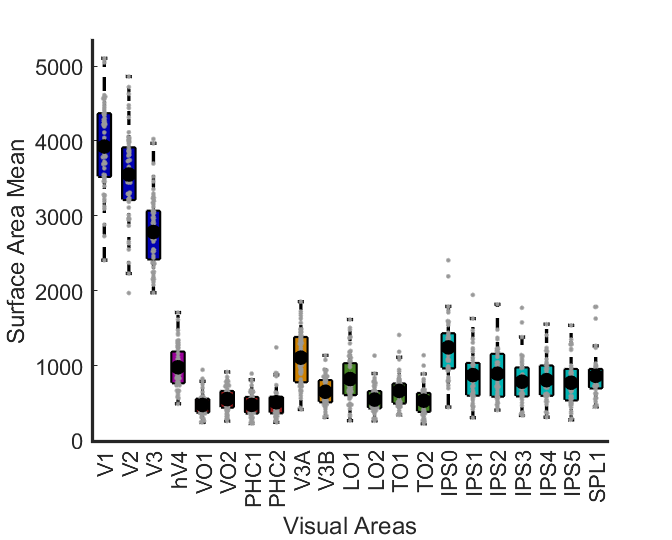

% create boxplot for each human visual map colored by the region
figure();
hold on
h=boxplot(sum_human','notch','off','colors',[0 0 0],'symbol','');
set(h,{'linew'},{2})
h = findobj(gca,'Tag','Box');
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),(colorscale_human_all_inv(j,:)),'FaceAlpha',1);
end
hold on
% plot gray dots for individual subjects and large black dot for average
plotSpread(sum_human','distributionColors',colorscale_human_all*0+[.6 .6 .6],'spreadWidth',.5)
plot(nanmean(sum_human'),'k.','MarkerSize',30);
xlim([0.5 size(sum_human,1)+.5])
yticks(0:1000:5000)

ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
ax.FontSize = 13;
set(gca,'xtick',[1:length(alllabels_human)],'xticklabel', alllabels_human);
xlabel('Visual Areas');
ylabel('Surface Area Mean');
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);

% display average range of each region based on max/min, reported in text
for i = 1:size(sum_human,1)
    area_range(i) = max(sum_human(i,:),[],'omitnan')/min(sum_human(i,:),[],'omitnan');
end

temp_rois = {1:4,ventralrois_human,dorsalrois_human,lateralrois_human,parietalrois_human};
for i = 1:length(temp_rois)
    disp(mean(area_range(temp_rois{i}),'all','omitnan'))
end

    2.5291

    4.1158

    4.0719

    4.9064

    5.1527



## Fig 2C: Normalized surface areas by visual field maps clusters and regions

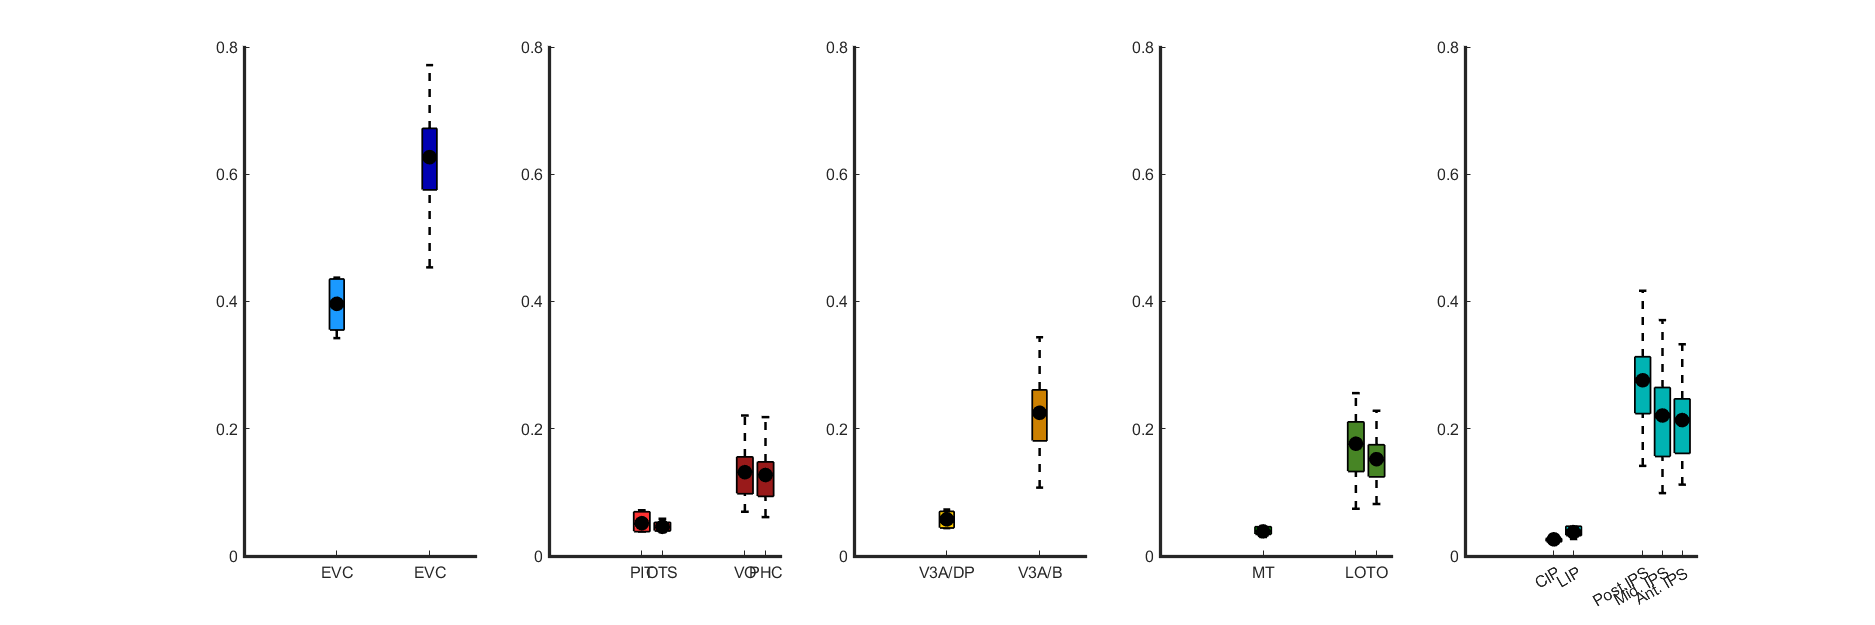

% average areas within map clusters and group into regions
map_clusters_human = {mean(normv1_human(2:4,:),1,'omitnan'),[mean(normv1_human(5:6,:),1,'omitnan');mean(normv1_human(7:8,:),1,'omitnan')],...
    mean(normv1_human(9:10,:),1,'omitnan'),[mean(normv1_human(11:12,:),1,'omitnan');mean(normv1_human(13:14,:),1,'omitnan')],...
    [mean(normv1_human(15:16,:),1,'omitnan');mean(normv1_human(17:18,:),1,'omitnan');mean(normv1_human(19:21,:),1,'omitnan')]};
cluster_name_human = {'EVC',{'VO','PHC'},'V3A/B',{'LO','TO'},{'Post.IPS','Mid. IPS','Ant. IPS'}};
cluster_color_human = [colorscale_region_human(1,:);colorscale_region_human(5:end,:)];

% average areas within map clusters and group into regions
map_clusters_monkey = {mean(normv1_monkey(2:5,:),1,'omitnan'),[mean(normv1_monkey(6:8,:),1,'omitnan');mean(normv1_monkey(9:10,:),1,'omitnan')],...
    mean(normv1_monkey(11:12,:),1,'omitnan'),mean(normv1_monkey(13:16,:),1,'omitnan'),...
    [mean(normv1_monkey(17:18,:),1,'omitnan');mean(normv1_monkey(19:21,:),1,'omitnan')]};
cluster_name_monkey = {'EVC',{'PIT','OTS'},'V3A/DP','MT',{'CIP','LIP'}};
cluster_color_monkey = [colorscale_region_monkey(1,:);colorscale_region_monkey(5:end,:)];

% I'm sure there is a more efficient way of plotting this data 
figure('Renderer', 'painters', 'Position', [10 10 1500 500]);
for i = 1:length(map_clusters_human)
    subplot(1,length(map_clusters_human),i);hold on;
    if size(map_clusters_monkey{i},1)==1
        h1 = boxplot(map_clusters_monkey{i}','colors',[0 0 0],'symbol','','Widths',0.15);
        set(h1,{'linew'},{1.5})
        h1 = findobj(gca,'Tag','Box');
        patch(get(h1,'XData'),get(h1,'YData'),cluster_color_monkey(i,:),'FaceAlpha',1);
        plot(1,nanmean(map_clusters_monkey{i}),'k.','MarkerSize',30);
        xt = 1;
    else
        h1 = boxplot([map_clusters_monkey{i}(1,:)',map_clusters_monkey{i}(2,:)'],[0.9, 1.1],'colors',[0 0 0],'symbol','','positions',[0.9, 1.1],'Widths',0.15);
        set(h1,{'linew'},{1.5})
        h1 = findobj(gca,'Tag','Box');
        patch(get(h1(1),'XData'),get(h1(1),'YData'),cluster_color_monkey(i,:),'FaceAlpha',1);
        patch(get(h1(2),'XData'),get(h1(2),'YData'),cluster_color_monkey(i,:),'FaceAlpha',1);
        plot([0.9 1.1],nanmean([map_clusters_monkey{i}(1,:)',map_clusters_monkey{i}(2,:)']),'k.','MarkerSize',30);
        xt = [0.9 1.1];
    end
    
    if size(map_clusters_human{i},1)==1
        h2 = boxplot(map_clusters_human{i}',2,'colors',[0 0 0],'symbol','','positions',2,'Widths',0.15);
        set(h2,{'linew'},{1.5})
        h2 = findobj(gca,'Tag','Box');
        patch(get(h2(1),'XData'),get(h2(1),'YData'),cluster_color_human(i,:),'FaceAlpha',1);
        plot(2,nanmean(map_clusters_human{i}),'k.','MarkerSize',30);
        xticks([xt 2])
        xticklabels({cluster_name_monkey{i},cluster_name_human{i}})
    elseif size(map_clusters_human{i},1)==2
        h2 = boxplot([map_clusters_human{i}(1,:)',map_clusters_human{i}(2,:)'],[1.9, 2.1],'colors',[0 0 0],'symbol','','positions',[1.9, 2.1],'Widths',0.15);
        set(h2,{'linew'},{1.5})
        h2 = findobj(gca,'Tag','Box');
        patch(get(h2(1),'XData'),get(h2(1),'YData'),cluster_color_human(i,:),'FaceAlpha',1);
        patch(get(h2(2),'XData'),get(h2(2),'YData'),cluster_color_human(i,:),'FaceAlpha',1);
        plot([1.9, 2.1],nanmean([map_clusters_human{i}(1,:)',map_clusters_human{i}(2,:)']),'k.','MarkerSize',30);
        xticks([xt 1.9 2.1])
        xticklabels([cluster_name_monkey{i},cluster_name_human{i}])
    else
        h2 = boxplot([map_clusters_human{i}(1,:)',map_clusters_human{i}(2,:)',map_clusters_human{i}(3,:)'],[1.8, 2, 2.2],'colors',[0 0 0],'symbol','','positions',[1.8, 2, 2.2],'Widths',0.15);
        set(h2,{'linew'},{1.5})
        h2 = findobj(gca,'Tag','Box');
        patch(get(h2(1),'XData'),get(h2(1),'YData'),cluster_color_human(i,:),'FaceAlpha',1);
        patch(get(h2(2),'XData'),get(h2(2),'YData'),cluster_color_human(i,:),'FaceAlpha',1);
        patch(get(h2(3),'XData'),get(h2(3),'YData'),cluster_color_human(i,:),'FaceAlpha',1);
        plot([1.8, 2, 2.2],nanmean([map_clusters_human{i}(1,:)',map_clusters_human{i}(2,:)',map_clusters_human{i}(3,:)']),'k.','MarkerSize',30);
        xticks([xt 1.8 2 2.2])
        xticklabels([cluster_name_monkey{i},cluster_name_human{i}])
    end
    box off;
    ax = gca;
    ax.XRuler.Axle.LineWidth = 2;
    ax.YRuler.Axle.LineWidth = 2;
    ylim([0 0.8])
    yticks(0:0.2:0.8)
end

## Fig 2D: Relative regional expansion for humans compared to macaques

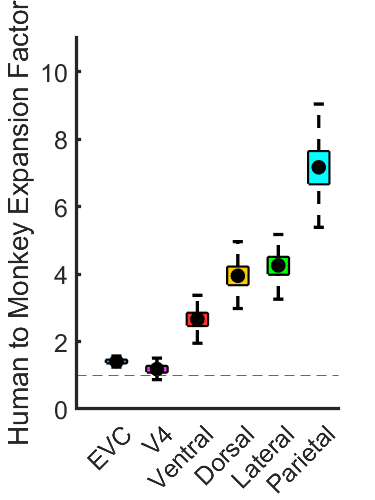

nResampling = 1000;
d = 1:size(cat_human,2);
% exclude V1 from region indices since everything is normalized to V1 size
temp_rois_human = {2:3,V4rois_human,ventralrois_human,dorsalrois_human,lateralrois_human,parietalrois_human};
temp_rois_monkey = {2:3,V4rois_monkey,ventralrois_monkey,dorsalrois_monkey,lateralrois_monkey,parietalrois_monkey};
% take samples of human data to match population of monkey data (n=6) and
% calculate expansion factor for each subsample
% expansion factor = mean of V1-normalized area sizes across all subjects and
% maps for humans / macaques, calculated for each anatomical region
data_monkey = zeros(length(temp_rois_human),nResampling);
for idx = 1:length(temp_rois_human)
    for res = 1:nResampling
        y = datasample(d,size(cat_monkey,2));
        data_monkey(idx,res) = mean(mean(cat_human(temp_rois_human{idx},y)./cat_human(1,y),2,'omitnan'))./mean(mean(cat_monkey(temp_rois_monkey{idx},:)./cat_monkey(1,:),2,'omitnan'));
    end
end

figure('Renderer', 'painters', 'Position', [10 10 300 400]);
hold on;
h1 = boxplot(data_monkey','colors',[0 0 0],'symbol','');
set(h1,{'linew'},{2})
h1 = findobj(gca,'Tag','Box');
for j=1:size(data_monkey,1)
   % have to extract x values from boxplot in order to set xlabels
   patch(get(h1(j),'XData'),get(h1(j),'YData'),colorscale_region_monkey_inv(j,:),'FaceAlpha',1);
end
% plot black dot for average expansion across samples
for j=1:size(data_monkey,1)
   plot(j,mean(data_monkey(j,:),'omitnan'),'k.','MarkerSize',30);
end

ax = gca;
ax.XAxis.TickLength = [0 0];
ax.FontSize = 15;
ax.LineWidth = 2;
ylabel('Human to Monkey Expansion Factor')
xticks(1:6)
xticklabels(alllabels_combined)
yline(1,'--')
box off;

## Fig 3A: Within-hemisphere (cross-subject) varability

% for each map, calculate variability as std/mean across subjects and
% bootstrapped error for Fig 3C
for i = 1:size(sum_human,1)
    norm_std_human(i) = std(sum_human(i,:),'omitnan')/mean(sum_human(i,:),'omitnan');
    std_boot_human(i,:) = bootstrp(1000,@(x) std(x,'omitnan')/mean(x,'omitnan'),sum_human(i,:));
end

for i = 1:size(sum_monkey,1)
    norm_std_monkey(i) = std(sum_monkey(i,:),'omitnan')/mean(sum_monkey(i,:),'omitnan');
    std_boot_monkey(i,:) = bootstrp(1000,@(x) std(x,'omitnan')/mean(x,'omitnan'),sum_monkey(i,:));
end

% group for visualization and calculate p value
all_norm_std = {norm_std_monkey norm_std_human};
groups = {ones(length(norm_std_monkey),1) ones(length(norm_std_human),1)*2};
[p,h,stats] = ranksum(norm_std_human,norm_std_monkey)

p = 0.0011

h = logical
   1


stats = struct with fields:
       zval: 3.2702
    ranksum: 582


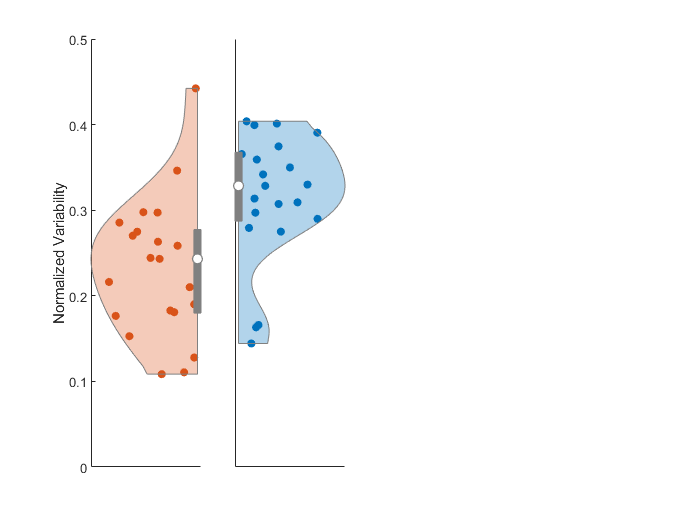


figure();
subplot(1,4,1)
violinplot(all_norm_std{1},groups{1},'HalfViolin','left','ViolinColor',monkey_orange);
ylabel('Normalized Variability')
% xticks([1,2])
% xticklabels('Monkeys')
ylim([0 0.5])
yticks([0:0.1:0.5])
xticks([])
box off;

subplot(1,4,2)
violinplot(all_norm_std{2},groups{2},'HalfViolin','right','ViolinColor',human_blue);
% ylabel('Normalized Variability')
% xticks([1,2])
% xticklabels('Humans')
ylim([0 0.5])
xticks([])
yticks([])
box off;

## Fig 3B: Cross-hemisphere (within-subject) variability

% normalize each area to the average across subjects for both hemis
surfacearea_human_norm{1} = cat_human(:,1:62) ./ mean(cat_human(:,1:62),2,'omitnan');
surfacearea_human_norm{2} = cat_human(:,63:end) ./ mean(cat_human(:,63:end),2,'omitnan');

surfacearea_monkey_norm{1} = cat_monkey(:,1:6) ./ mean(cat_monkey(:,1:6),2,'omitnan');
surfacearea_monkey_norm{2} = cat_monkey(:,7:end) ./ mean(cat_monkey(:,7:end),2,'omitnan');

% take R-L hemisphere difference
data1 = surfacearea_human_norm{1}-surfacearea_human_norm{2};
data2 = surfacearea_monkey_norm{1}-surfacearea_monkey_norm{2};

% resample human population to match population of monkey data (n=6) and
% take average p value
for i = 1:1000
    idx = datasample(1:size(data1,2),size(data2,2));
    data1_new = data1(:,idx);
    d1 = data1_new(:);d2 = data2(:);
    include1 = ~isnan(d1);include2 = ~isnan(d2);
    d1 = d1(include1);d2 = d2(include2);
    [h,p] = vartest2(d1,d2);
    all_p(i) = p;
end

disp(['Resampled Two Sample F Test: p = ',num2str(mean(all_p))])

Resampled Two Sample F Test: p = 0.0064247



% take std of hemi difference and bootstrap values for error bars in Fig 3C
nboot = 1000;
h_data = std(data1,[],2,'omitnan');
h_data_boot = bootstrp(nboot,@(x) std(x,[],2,'omitnan'),data1);
m_data = std(data2,[],2,'omitnan');
m_data_boot = bootstrp(nboot,@(x) std(x,[],2,'omitnan'),data2);

[p,h,stats] = ranksum(h_data,m_data)

p = 3.5411e-04

h = logical
   1


stats = struct with fields:
       zval: 3.5721
    ranksum: 594


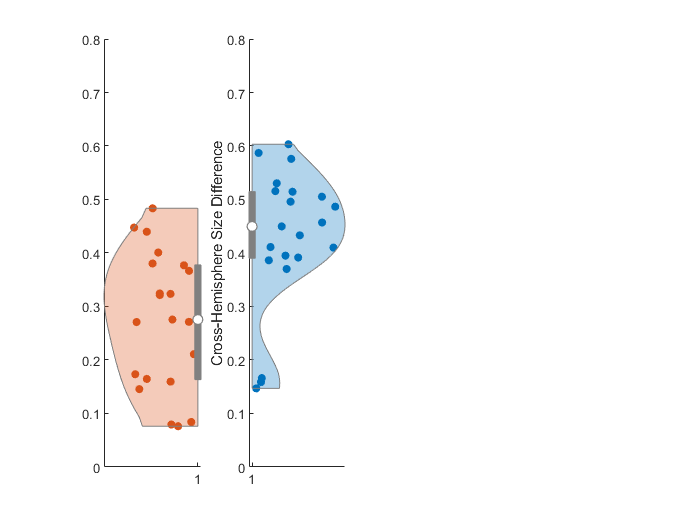


figure();
subplot(1,4,2)
violinplot(h_data,ones(1,length(h_data))','HalfViolin','right','ViolinColor',human_blue);
ylabel('Cross-Hemisphere Size Difference')
% xticks([1,2])
% xticklabels('Humans')
ylim([0 0.8])
% yticks(-2:1:2)
box off;

subplot(1,4,1)
violinplot(m_data,ones(1,length(m_data))','HalfViolin','left','ViolinColor',monkey_orange);
% ylabel('Normalized Variability')
% xticks([1,2])
% xticklabels('Monkeys')
ylim([0 0.8])
% yticks(-2:1:2)
box off;

## Fig 3C: Comparison of within- and cross-hemisphere variability

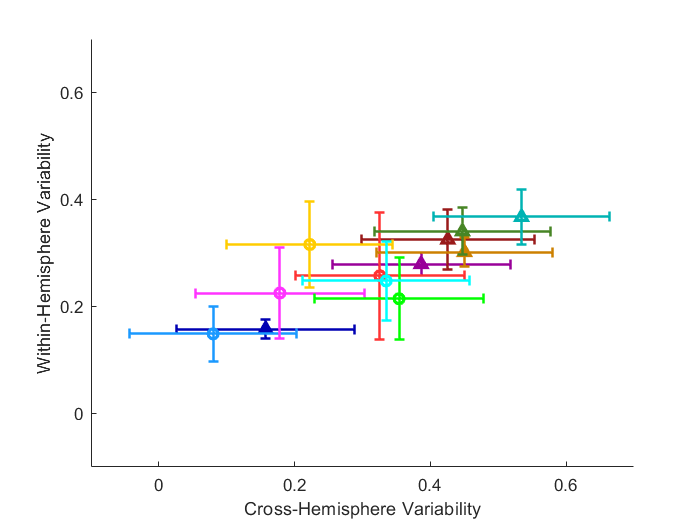

% plotting within vs cross hemisphere variability with horizontal and
% vertical error bars
figure();
hold on;
for i = 1:size(colorscale_unique_human,1)
plot(mean(h_data(region_rois_human{i})),mean(norm_std_human(region_rois_human{i})),'-^','Color',colorscale_unique_human(i,:),'LineWidth',2)
all_err = h_data_boot(:,region_rois_human{i});
all_err = all_err(:);
errorbar(mean(h_data(region_rois_human{i})),mean(norm_std_human(region_rois_human{i})),std(all_err),'horizontal','Color',colorscale_unique_human(i,:),'LineWidth',1.5)
all_err = std_boot_human(region_rois_human{i},:);
all_err = all_err(:);
errorbar(mean(h_data(region_rois_human{i})),mean(norm_std_human(region_rois_human{i})),std(all_err),'vertical','Color',colorscale_unique_human(i,:),'LineWidth',1.5)

plot(mean(m_data(region_rois_monkey{i})),mean(norm_std_monkey(region_rois_monkey{i})),'-o','Color',colorscale_unique_monkey(i,:),'LineWidth',2)
all_err = m_data_boot(:,region_rois_monkey{i});
all_err = all_err(:);
errorbar(mean(m_data(region_rois_monkey{i})),mean(norm_std_monkey(region_rois_monkey{i})),std(all_err),'horizontal','Color',colorscale_unique_monkey(i,:),'LineWidth',1.5)
all_err = std_boot_monkey(region_rois_monkey{i},:);
all_err = all_err(:);
errorbar(mean(m_data(region_rois_monkey{i})),mean(norm_std_monkey(region_rois_monkey{i})),std(all_err),'vertical','Color',colorscale_unique_monkey(i,:),'LineWidth',1.5)
end
xlim([-0.1 0.7])
xticks([0:0.2:0.6])
ylim([-0.1 0.7])
yticks([0:0.2:0.6])
xlabel('Cross-Hemisphere Variability')
ylabel('Within-Hemisphere Variability')

## Supp Fig 6: Surface area measurements of neonates

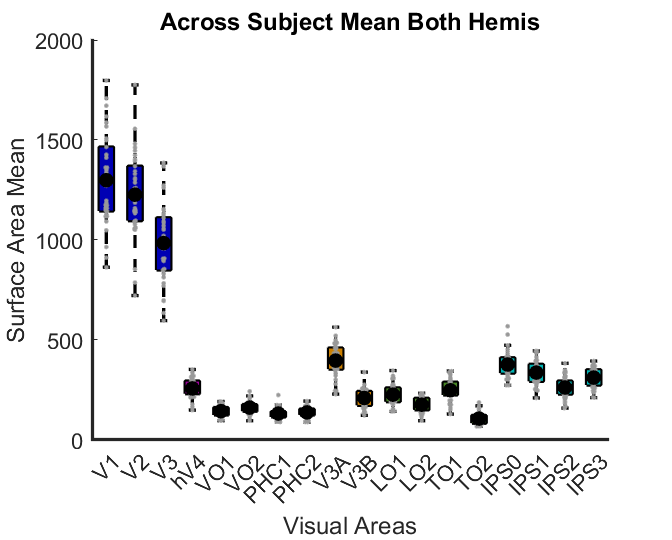

% plot raw surface area boxplots for neonate data
figure;hold on;
h=boxplot(sum_neo(1:end-3,:)','notch','off','colors',[0 0 0],'symbol','');
set(h,{'linew'},{2})
h = findobj(gca,'Tag','Box');
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),(colorscale_human_all_inv(j+3,:)),'FaceAlpha',1);
end
hold on
plotSpread(sum_neo(1:end-3,:)','distributionColors',colorscale_human_all(4:end,:)*0+[.6 .6 .6],'spreadWidth',.5)
plot(nanmean(sum_neo(1:end-3,:)'),'k.','MarkerSize',30);
xlim([0.5 size(sum_neo(1:end-3,:),1)+.5])
ylim([0 2000])
yticks(0:500:2000)
ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
ax.FontSize = 13;
set(gca,'xtick',[1:length(alllabels_human)],'xticklabel', alllabels_human);
xlabel('Visual Areas');
ylabel('Surface Area Mean');
title('Across Subject Mean Both Hemis')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);

## Fig 4A: Normalized neonate surface area by visual field maps clusters and regions

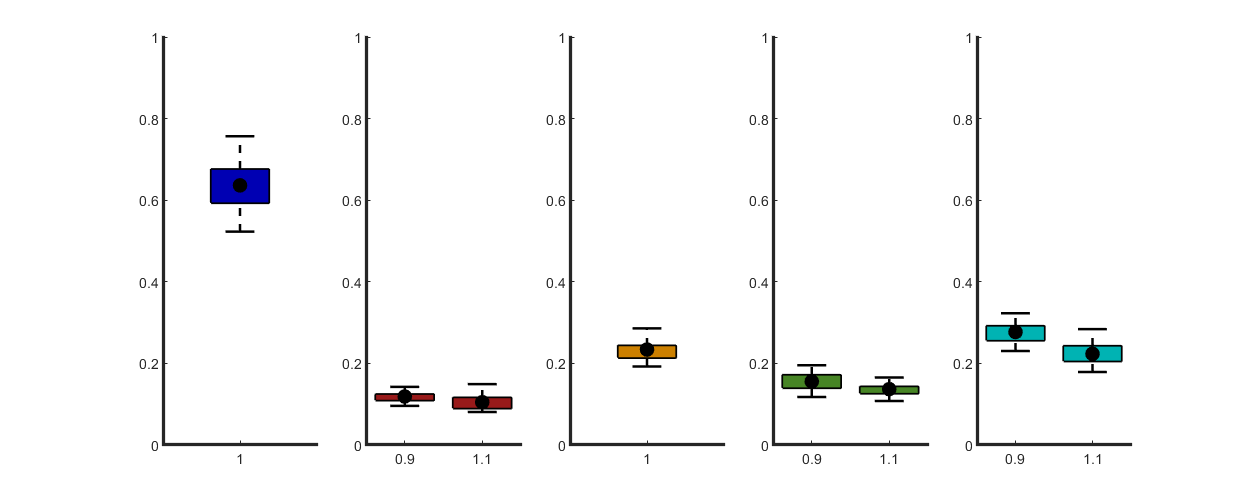

% normalize to each subjects' V1 sizes
normv1_neo = sum_neo./sum_neo(1,:);

% average areas within map clusters and group into regions
map_clusters_neo = {mean(normv1_neo(2:4,:),1,'omitnan'),[mean(normv1_neo(5:6,:),1,'omitnan');mean(normv1_neo(7:8,:),1,'omitnan')],...
    mean(normv1_neo(9:10,:),1,'omitnan'),[mean(normv1_neo(11:12,:),1,'omitnan');mean(normv1_neo(13:14,:),1,'omitnan')],...
    [mean(normv1_neo(15:16,:),1,'omitnan');mean(normv1_neo(17:18,:),1,'omitnan');mean(normv1_neo(19:21,:),1,'omitnan')]};
cluster_name_neo = {'EVC',{'VO','PHC'},'V3A/B',{'LO','TO'},{'Post.IPS','Mid. IPS','Ant. IPS'}};
cluster_color_neo = [colorscale_region_human(1,:);colorscale_region_human(5:end,:)];

figure('Renderer', 'painters', 'Position', [10 10 1000 400]);
for i = 1:length(map_clusters_human)
    subplot(1,length(map_clusters_human),i);hold on;
    if size(map_clusters_neo{i},1)==1
        h1 = boxplot(map_clusters_neo{i}','colors',[0 0 0],'symbol','','Widths',0.15);
        set(h1,{'linew'},{1.5})
        h1 = findobj(gca,'Tag','Box');
        patch(get(h1,'XData'),get(h1,'YData'),cluster_color_neo(i,:),'FaceAlpha',1);
        plot(1,nanmean(map_clusters_neo{i}),'k.','MarkerSize',30);
        xt = 1;
    else
        h1 = boxplot([map_clusters_neo{i}(1,:)',map_clusters_neo{i}(2,:)'],[0.9, 1.1],'colors',[0 0 0],'symbol','','positions',[0.9, 1.1],'Widths',0.15);
        set(h1,{'linew'},{1.5})
        h1 = findobj(gca,'Tag','Box');
        patch(get(h1(1),'XData'),get(h1(1),'YData'),cluster_color_neo(i,:),'FaceAlpha',1);
        patch(get(h1(2),'XData'),get(h1(2),'YData'),cluster_color_neo(i,:),'FaceAlpha',1);
        plot([0.9 1.1],nanmean([map_clusters_neo{i}(1,:)',map_clusters_neo{i}(2,:)']),'k.','MarkerSize',30);
        xt = [0.9 1.1];
    end
    box off;
    ax = gca;
    ax.XRuler.Axle.LineWidth = 2;
    ax.YRuler.Axle.LineWidth = 2;
    yticks(0:0.2:1)
    ylim([0 1])
    xlim([0.8 1.2])
end

## Fig 4B: Relative regional expansion for neonatal humans compared to macaques and adult humans

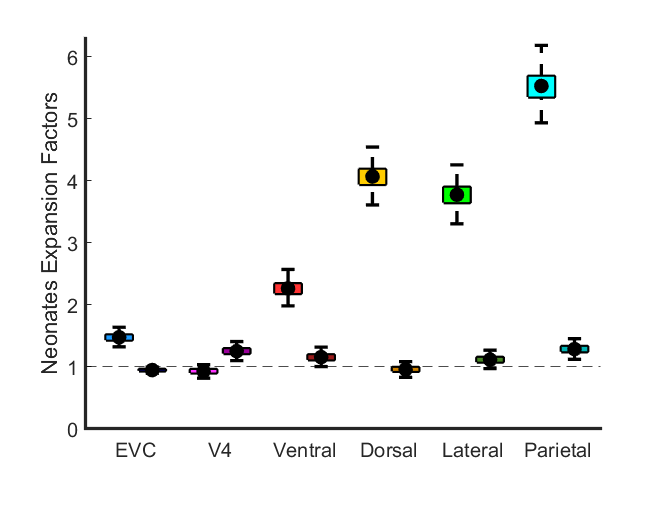

% exclude V1 index since areas are normalized to V1
temp_rois_human = {2:3,V4rois_human,ventralrois_human,dorsalrois_human,lateralrois_human,parietalrois_human};
temp_rois_monkey = {2:3,V4rois_monkey,ventralrois_monkey,dorsalrois_monkey,lateralrois_monkey,parietalrois_monkey};

% resample neonate human population to match monkey (n=6), resample adult
% human to match neonate human population (n=34) for comparable
% measurements
nResampling = 1000;
d_neo = 1:size(sum_neo,2);
d_human = 1:size(sum_human,2);
data_monkey = zeros(length(temp_rois_human),nResampling);
data_human = zeros(length(temp_rois_human),nResampling);
for idx = 1:length(temp_rois_human)
    for res = 1:nResampling
        y = datasample(d_neo,size(sum_monkey,2));
        data_monkey(idx,res) = mean(mean(sum_neo(temp_rois_human{idx},y)./sum_neo(1,y),2,'omitnan'))./mean(mean(sum_monkey(temp_rois_monkey{idx},:)./sum_monkey(1,:),2,'omitnan'));
        y = datasample(d_human,size(sum_neo,2));
        data_human(idx,res) = mean(mean(sum_human(temp_rois_human{idx},y)./sum_human(1,y),2,'omitnan'))./mean(mean(sum_neo(temp_rois_human{idx},:)./sum_neo(1,:),2,'omitnan'));
    end
end

% group for visualization
concat_data = [];
concat_colorscale = [];
for i = 1:size(data_human,1)
    concat_data = [concat_data; data_monkey(i,:); data_human(i,:)];
    concat_colorscale = [concat_colorscale; colorscale_region_human_inv(i,:); colorscale_region_monkey_inv(i,:)];
end

g1 = sort([1:6,1:6]);
g2 = repmat(1:2,[1,6]);

% plot boxplots for neonate/adult human and neonate/macaque expansion
figure('Renderer', 'painters', 'Position', [10 10 1500 500]);
hold on
h1=boxplot(concat_data',[g1' g2'],'factorgap',5,'colors',[0 0 0],'symbol','','Widths',0.8);
set(h1,{'linew'},{2})
h1 = findobj(gca,'Tag','Box');
for j=1:size(concat_data,1)
   % have to extract x values from boxplot in order to set xlabels
   xdat{j} = get(h1(j),'XData');
   xd(j) = (xdat{j}(3)+xdat{j}(2))/2;
   patch(get(h1(j),'XData'),get(h1(j),'YData'),concat_colorscale(j,:),'FaceAlpha',1);
end

% plotSpread(concat_data','xValues',fliplr(xd),'distributionColors',concat_colorscale*0+[.6 .6 .6],'spreadWidth',.5)
plot(fliplr(xd),nanmean(concat_data'),'k.','MarkerSize',30);
yline(1,'k--')

% take average of x values for each area to put xticklabel in the middle
xt = [];
for i = 1:length(xd)/2
    xt(i) = (xd(2*i-1) + xd(2*i))/2;
end

ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',fliplr(xt),'xticklabel', alllabels_combined,'fontsize',12);
% xlabel('Visual Areas');
ylabel('Neonates Expansion Factors');
% title('Normalization by Combined V1 Surface Area')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
ylim([0 6.3])

## Fig 5A: Correlations between extrastriate maps and V1

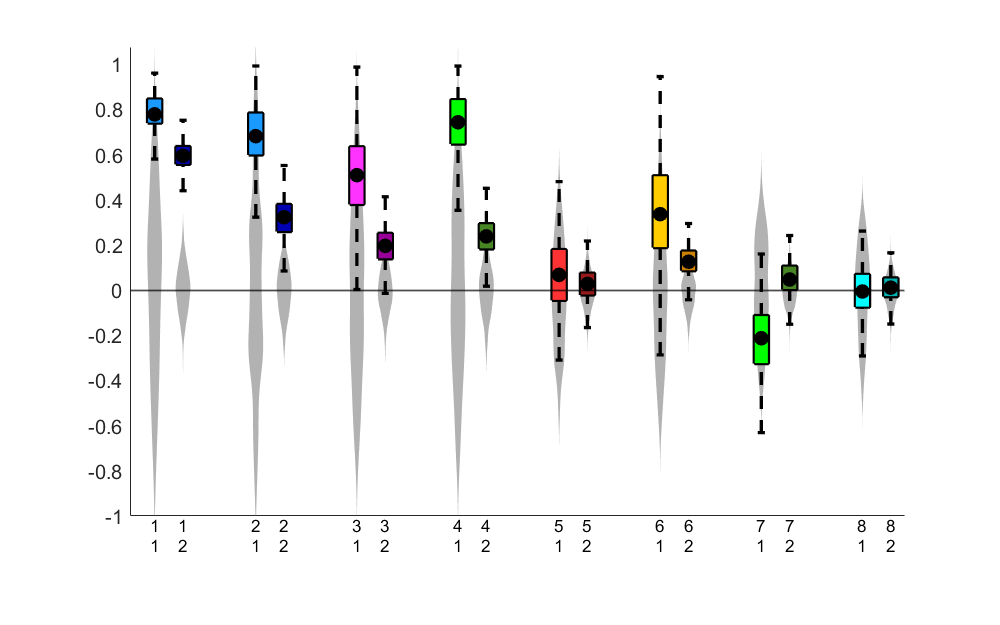

% group to display individual EVC areas, MT/TO1, then remaining regions 
areas_human = {cat_human(2,:),cat_human(3,:),cat_human(4,:),cat_human(13,:),cat_human(5:8,:),cat_human(9:10,:),cat_human([11:12,14],:),cat_human(15:21,:)};
areas_monkey = {cat_monkey(2,:),cat_monkey(3,:),cat_monkey(4,:),cat_monkey(13,:),...
    cat_monkey(6:10,:),cat_monkey(11:12,:),cat_monkey(14:16,:),cat_monkey(17:21,:)};

% initialize correlations with V1, bootstrapped corrs and permutations
r_human = [];
r_human_boot = {};
p_human = [];
r_monkey = [];
r_monkey_boot = {};
p_monkey = [];
r_perm_human = {};
r_perm_monkey = {};
for i = 1:length(areas_human)
    % correlations of area sizes with V1 size across subjects with
    % bootstrapped correlations
    r_human(i) = mean(corr(areas_human{i}',cat_human(1,:)','Rows','complete'));
    r_human_boot{i} = bootstrp(1000,@(x,y) mean(corr(x,y,'Rows','complete')),areas_human{i}',cat_human(1,:)');
    
    r_monkey(i) = mean(corr(areas_monkey{i}',cat_monkey(1,:)','Rows','complete'));
    r_monkey_boot{i} = bootstrp(1000,@(x,y) mean(corr(x,y,'Rows','complete')),areas_monkey{i}',cat_monkey(1,:)');
    % perform 1000 permutations of subject indices for null distribution
    for j = 1:1000
        nSub_human = size(cat_human,2)/2;
        idx1 = randperm(nSub_human);
        idx2 = randperm(nSub_human);
        r_perm_human{i}(j) = mean(corr(areas_human{i}(:,[idx1 idx1+nSub_human])',cat_human(1,:)','Rows','complete'));
        
        nSub_monkey = size(cat_monkey,2)/2;
        idx1 = randperm(nSub_monkey);
        idx2 = randperm(nSub_monkey);
        r_perm_monkey{i}(j) = mean(corr(areas_monkey{i}(:,[idx1 idx1+nSub_monkey])',cat_monkey(1,:)','Rows','complete'));
    end
    
    % determine if correlation surpasses 95 or 97.5 percentile of null
    % distribution. considered significant if >97.5 and trending if >95
    % percentile
    CI95_human = mean(r_perm_human{i}) + 1.64*(std(r_perm_human{i}));
    p_human95(i) = mean(r_human(i))>CI95_human;
    CI975_human = mean(r_perm_human{i}) + 1.96*(std(r_perm_human{i}));
    p_human975(i) = mean(r_human(i))>CI975_human;

    CI95_monkey = mean(r_perm_monkey{i}) + 1.64*(std(r_perm_monkey{i}));
    p_monkey95(i) = mean(r_monkey(i))>CI95_monkey;
    CI975_monkey = mean(r_perm_monkey{i}) + 1.96*(std(r_perm_monkey{i}));
    p_monkey975(i) = mean(r_monkey(i))>CI975_monkey;
end

mx = 1:3:3*8;hx = 2:3:3*8+1;
h_color = [colorscale_region_human([2:4,7],:);colorscale_region_human(5:end,:)];
m_color = [colorscale_region_monkey([2:4,7],:);colorscale_region_monkey(5:end,:)];

% group for visualization
rvals = [];
bootvals = [];
cvals = [];
permvals = [];
for i = 1:length(areas_human)
    rvals = [rvals r_monkey(i) r_human(i)];
    bootvals = [bootvals r_monkey_boot{i} r_human_boot{i}];
    cvals = [cvals; m_color(i,:); h_color(i,:)];
    permvals = [permvals; r_perm_monkey{i}; r_perm_human{i}];
end

g1 = sort([1:8,1:8]);
g2 = repmat(1:2,[1,8]);
cvals = flipud(cvals);

figure('Renderer', 'painters', 'Position', [10 10 800 500]);hold on;
yline(0,'k-','LineWidth',1)
% plot boxplots of correlations - need to replot over null distributions
% but need h1 to set x values
h1 = boxplot(bootvals,[g1' g2'],'factorgap',[13 1],'colors',[0 0 0],'symbol','');

% plot null distributions
set(h1,{'linew'},{2})
h1 = findobj(gca,'Tag','Box');
for j=1:size(cvals,1)
   temp = get(h1(j),'XData');
   violin(permvals(size(permvals,1)-j+1,:)','x',(temp(1)+temp(3))/2,'edgecolor','none','facecolor',[0.4 0.4 0.4],'mc',[],'medc',[]);
end

% plot boxplots of correlations
h1 = boxplot(bootvals,[g1' g2'],'factorgap',[13 1],'colors',[0 0 0],'symbol','');
set(h1,{'linew'},{2})
h1 = findobj(gca,'Tag','Box');
for j=1:size(cvals,1)
   patch(get(h1(j),'XData'),get(h1(j),'YData'),cvals(j,:),'FaceAlpha',1);
end

xd = [];
for j=1:size(cvals,1)
    i = size(cvals,1)+1-j;
   % have to extract x values from boxplot in order to set xlabels
   xdat{j} = get(h1(j),'XData');
   xd(j) = (xdat{j}(3)+xdat{j}(2))/2;
   plot(xd(j),rvals(i),'k.','MarkerSize',30);
end

box off;

## Fig 5B: Correlations between extrastriate maps and V1 based on distance

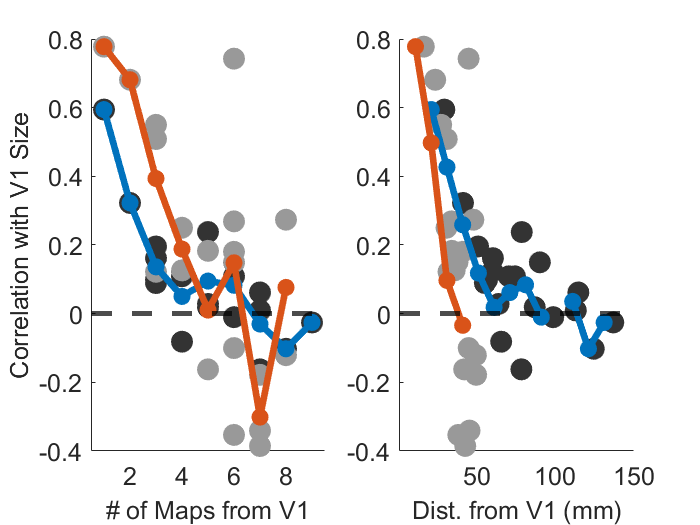

% average distance from V1 across subjects
meanmonks_cortdist_rh=mean(monkey_data.dist_from_v1_rh,2,'omitnan');
meanmonks_cortdist_lh=mean(monkey_data.dist_from_v1_lh,2,'omitnan');

% sum across ventral & dorsal components for EVC
meanmonks_cortdist_rh1234=[];
meanmonks_cortdist_rh1234(1)=[meanmonks_cortdist_rh(1)+meanmonks_cortdist_rh(2)];
meanmonks_cortdist_rh1234(2)=[meanmonks_cortdist_rh(3)+meanmonks_cortdist_rh(4)]/2;
meanmonks_cortdist_rh1234(3)=[meanmonks_cortdist_rh(5)+meanmonks_cortdist_rh(6)]/2;
meanmonks_cortdist_rh1234(4)=[meanmonks_cortdist_rh(7)+meanmonks_cortdist_rh(8)]/2;
meanmonks_cortdist_rh1234(5)=[meanmonks_cortdist_rh(9)+meanmonks_cortdist_rh(10)]/2;
meanmonks_cortdist_rh1234=[meanmonks_cortdist_rh1234,meanmonks_cortdist_rh(11:end)'];

meanmonks_cortdist_lh1234=[];
meanmonks_cortdist_lh1234(1)=[meanmonks_cortdist_lh(1)+meanmonks_cortdist_lh(2)];
meanmonks_cortdist_lh1234(2)=[meanmonks_cortdist_lh(3)+meanmonks_cortdist_lh(4)]/2;
meanmonks_cortdist_lh1234(3)=[meanmonks_cortdist_lh(5)+meanmonks_cortdist_lh(6)]/2;
meanmonks_cortdist_lh1234(4)=[meanmonks_cortdist_lh(7)+meanmonks_cortdist_lh(8)]/2;
meanmonks_cortdist_lh1234(5)=[meanmonks_cortdist_lh(9)+meanmonks_cortdist_lh(10)]/2;
meanmonks_cortdist_lh1234=[meanmonks_cortdist_lh1234,meanmonks_cortdist_lh(11:end)'];

% average across hemispheres
meanmonks_cortdist1234=[meanmonks_cortdist_rh1234+meanmonks_cortdist_lh1234]/2;

% average distance from V1 across subjects
meanhumans_cortdist_rh = mean(human_data.dist_from_v1_rh,2,'omitnan');
meanhumans_cortdist_lh = mean(human_data.dist_from_v1_lh,2,'omitnan');

% sum across ventral & dorsal components for EVC
meanhumans_cortdist_rh1234=[];
meanhumans_cortdist_rh1234(1)=0;
meanhumans_cortdist_rh1234(2)=[meanhumans_cortdist_rh(3)+meanhumans_cortdist_rh(4)]/2;
meanhumans_cortdist_rh1234(3)=[meanhumans_cortdist_rh(5)+meanhumans_cortdist_rh(6)]/2;
meanhumans_cortdist_rh1234=[meanhumans_cortdist_rh1234,meanhumans_cortdist_rh(7:end)'];

meanhumans_cortdist_lh1234=[];
meanhumans_cortdist_lh1234(1)=0;
meanhumans_cortdist_lh1234(2)=[meanhumans_cortdist_lh(3)+meanhumans_cortdist_lh(4)]/2;
meanhumans_cortdist_lh1234(3)=[meanhumans_cortdist_lh(5)+meanhumans_cortdist_lh(6)]/2;
meanhumans_cortdist_lh1234=[meanhumans_cortdist_lh1234,meanhumans_cortdist_lh(7:end)'];

% average across hemispheres
meanhumans_cortdist1234=[meanhumans_cortdist_rh1234+meanhumans_cortdist_lh1234]/2;

% extract distance from V1 for each area
human_areadistfromV1 = human_data.areadistfromV1;
monk_areadistfromV1= monkey_data.areadistfromV1;

% calculate correlations of each area with V1 across subjects
human_v1_corr = zeros(1,size(cat_human,1));
monkey_v1_corr = zeros(1,size(cat_monkey,1));
human_v1_corr_ci = zeros(size(cat_human,1),10000);
monkey_v1_corr_ci = zeros(size(cat_monkey,1),10000);
for ii = 1:size(cat_human,1)
    exclude_nan = find(~isnan(cat_human(ii,:)));
    SA_area = cat_human(ii,exclude_nan);
    SA_v1 = cat_human(1,exclude_nan);
    human_v1_corr(ii) = corr2(SA_area,SA_v1);
    
    exclude_nan = find(~isnan(cat_monkey(ii,:)));
    SA_area = cat_monkey(ii,exclude_nan);
    SA_v1 = cat_monkey(1,exclude_nan);
    monkey_v1_corr(ii) = corr2(SA_area,SA_v1);
end

% for each distance increment from V1, calculate the average correlation
% for any areas at that distance
for x = 1:max([monk_areadistfromV1,human_areadistfromV1])
    human_meanareadist(x)=nanmean(human_v1_corr(human_areadistfromV1==x)); 
    monk_meanareadist(x)=nanmean(monkey_v1_corr(monk_areadistfromV1==x));
end

% determine distance bins for correlations in each bin
stepsize=10;
maxrange=150;
human_meancortdist=nan(length(1:stepsize:maxrange),1);
monk_meancortdist=nan(length(1:stepsize:maxrange),1);
count = 0;
for x = 1:stepsize:maxrange
    count = count+1;
    if x < 150
        if sum([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<(x+stepsize)]) > 1
            monk_meancortdist(count)=nanmean(monkey_v1_corr([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<x+stepsize]));
        elseif sum([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<(x+stepsize)])
            monk_meancortdist(count)=monkey_v1_corr([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<(x+stepsize)]);
        end
        if sum([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)]) > 1
            human_meancortdist(count)=nanmean(human_v1_corr([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)]));
        elseif sum([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)])
            human_meancortdist(count)=human_v1_corr([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)]);
        end
    end
end
human_meancortdist(4)=[human_meancortdist(3)+human_meancortdist(5)]/2;

% plot individual and average correlations with V1 based on number of maps
% from V1
figure();
subplot(1,2,1)
hold on
plot(human_areadistfromV1(2:end),human_v1_corr(2:end),'.','color',[.2 .2 .2],'MarkerSize',45)
plot(monk_areadistfromV1(2:end),monkey_v1_corr(2:end),'.','color',[.6 .6 .6],'MarkerSize',45) 
plot(human_meanareadist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0 0.4470 0.7410])
plot(monk_meanareadist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0.8500 0.3250 0.0980])
yline(0,'k--','LineWidth',3)
box off
ax = gca;
ax.XAxis.TickLength = [0 0];
ax.FontSize = 15;
xlim([0.5 max([monk_areadistfromV1,human_areadistfromV1])+.5])
xlabel('# of Maps from V1','Fontsize',15)
ylabel('Correlation with V1 Size','fontsize',15)

% plot individual and average correlations with V1 based on cortical
% distance from V1
subplot(1,2,2) 
hold on
plot(meanhumans_cortdist1234(2:end),human_v1_corr(2:end),'.','color',[.2 .2 .2],'MarkerSize',45)
plot(meanmonks_cortdist1234(2:end),monkey_v1_corr(2:end),'.','color',[.6 .6 .6],'MarkerSize',45) 
plot(1:stepsize:maxrange,human_meancortdist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0 0.4470 0.7410])
plot(1:stepsize:maxrange,monk_meancortdist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0.8500 0.3250 0.0980])
yline(0,'k--','LineWidth',3)
box off
ax = gca;
ax.XAxis.TickLength = [0 0];
ax.FontSize = 15;
xlim([0.5 150])
xlabel('Dist. from V1 (mm)','fontsize',15)